# Practica 1 - Métodos directos de resolución de sistemas lineales, $Ax = b$

## Problema 2

Consideremos el sistema lineal $Ax = b$, de tamaño $n \times  n$, donde $A = (a_{ij})$ es una matriz simétrica tal que

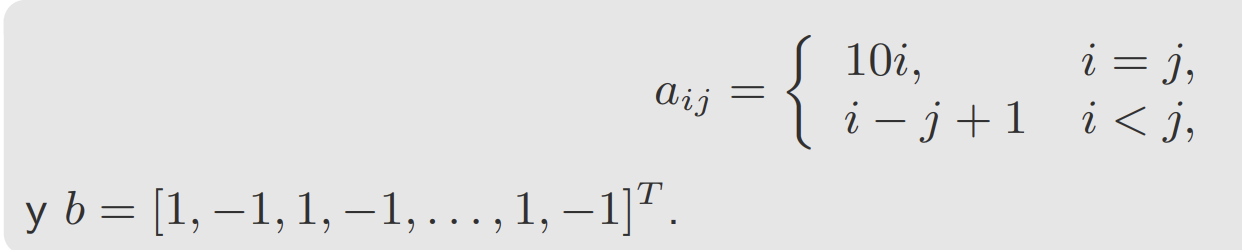

### (a) Escribe el programa que has elaborado para construir la matriz $A$ y el vector $b$. ¿Tiene el sistema $Ax = b$ solución única cuando $n = 1000$?

Creamos la función Practica1_2matriz(n) para manejar la creación de la matriz. El archivo .m está en esta misma carpeta. Luego, creamos la matriz con $n=1000$, y usando el metodo de Rouche-Frobenius, programa RF(A, b), obtenemos que es sistema compatible determinado, y por tanto, tiene solución única.

[A, b] = Practica1_2matriz(1000);
RF(A, b)

Es sistema compatible determinado.


### (b) ¿Es la matriz A definida positiva, para $n = 10$? En caso afirmativo, utiliza la factorización de Cholesky, la sustitución directa y la sustitución inversa para resolver el sistema. Proporciona la matriz $L$. 

Ahora, hacemos una segunda llamada al programa de la pregunta, con $n=10$. Luego, usamos la función DefinidaPositiva(A) para comprobar que la matriz es definida positiva.

[A, b] = Practica1_2matriz(10);
DefinidaPositiva(A);

DEFINIDA POSITIVA.


Luego, como lo és, utilizaremos la factorización de Cholesky para resolver el sistema, usando ademas la sustictucion directa e inversa.

L = FactorizacionCholesky(A)

L =     3.1623         0         0         0         0         0         0         0         0         0
         0    4.4721         0         0         0         0         0         0         0         0
   -0.3162         0    5.4681         0         0         0         0         0         0         0
   -0.6325   -0.2236   -0.0366    6.2888         0         0         0         0         0         0
   -0.9487   -0.4472   -0.2377   -0.1127    6.9879         0         0         0         0         0
   -1.2649   -0.6708   -0.4389   -0.3126   -0.2346    7.5898         0         0         0         0
   -1.5811   -0.8944   -0.6401   -0.5126   -0.4450   -0.4145    8.1029         0         0         0
   -1.8974   -1.1180   -0.8412   -0.7125   -0.6555   -0.6450   -0.6742    8.5226         0         0
   -2.2136   -1.3416   -1.0424   -0.9124   -0.8659   -0.8756   -0.9359   -1.0549    8.8247         0
   -2.5298   -1.5652   -1.2436   -1.1124   -1.0763   -1.1062   -1.1975   -1.3629   -1.6


% Usamos la funcion ResolucionDirectaCholesky(A, b)
% que resuelve el sistema usando esta factorizacion

sol = ResolucionDirectaCholesky(A, b)

sol =     0.1334
   -0.0380
    0.0441
   -0.0161
    0.0291
   -0.0077
    0.0238
   -0.0026
    0.0218
    0.0012


Comprobamos que sea solucion viendo que la diferencia $A \cdot sol - b$ es muy cercana a 0

dif = A * sol - b

dif = 1.0e-15 *

    0.2220
    0.1110
    0.2220
         0
   -0.2220
         0
    0.2220
   -0.2220
         0
   -0.2220


### (c) ¿Sigue siendo la matriz definida positiva para $n = 500$? Si no lo es, utiliza la factorización de Crout para resolver el sistema. Proporciona las matrices $L$ y $D$.

Usamos la funcion del problema para obtener la A con $n=500$, y luego, comprobamos si es definida positiva.

[A, b] = Practica1_2matriz(500);
DefinidaPositiva(A);

NO DEFINIDA POSITIVA.


Vemos que no es definida positiva, por lo que usaremos la factorizacion de Crout.

[L, D] = FactorizacionCrout(A)

L =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

D = 1.0e+03 *

    0.0100
    0.0200
    0.0299
    0.0395
    0.0488
    0.0576
    0.0657
    0.0726
    0.0779
    0.0800



% Usamos la funcion ResolucionDirectaFactCrout(A, b)
% que resuelve el sistema usando esta factorizacion

sol = ResolucionDirectaFactCrout(A, b)

sol =     0.0697
   -0.0649
    0.0268
   -0.0297
    0.0173
   -0.0189
    0.0128
   -0.0138
    0.0103
   -0.0108


Comprobamos que sea solucion viendo que la diferencia $A \cdot sol - b$ es muy cercana a 0

dif = A * sol - b

dif = 1.0e-10 *

    0.0000
    0.0000
   -0.0000
   -0.0001
    0.0000
    0.0001
    0.0001
    0.0001
   -0.0001
    0.0000
